clc;
clear all
close all

% Parameters
% Parameters
p_s = 0.03;
num_generations = 25;

% Define plasmid states explicitly ordered from fully auxotroph to fully prototroph
plasmid_labels = {'-', 'M', 'U', 'L', 'H', 'UM', 'LM', 'LU', 'HM', 'HU', 'HL', 'LUM', 'HUM', 'HLM', 'HLU', 'HLUM'};
states = [0 0 0 0;
          0 0 0 1;
          0 0 1 0;
          0 1 0 0;
          1 0 0 0;
          0 0 1 1;
          0 1 0 1;
          0 1 1 0;
          1 0 0 1;
          1 0 1 0;
          1 1 0 0;
          0 1 1 1;
          1 0 1 1;
          1 1 0 1;
          1 1 1 0;
          1 1 1 1];

% Transition Matrix T 16 x 16
% This transition matrix evaluates the probability of having a new
% daughter cell of type (j) from the parent cell of type (i)
T = zeros(16,16);
for i = 1:16 %loop in the type of parent cell
    for j = 1:16 %loop in the type of daughter cell
        prob=1; %restart the calculations
        for plasmid = 1:4 %loop in the number of plasmids the daughter cell defer from the parent cell
            if (states(i,plasmid) == 1 && states(j,plasmid) == 0)
                prob = prob*p_s;
            % elsif (states(i,plasmid) == 0 && states(j,plasmid) == 0)
            %     prob = prob*(1-p_s);
            elseif (states(i,plasmid) == 0 && states(j,plasmid) == 1)
                prob = 0; % cannot regain plasmid
                break;
            end
        end
        T(i,j) = prob;
    end
    if(i>1)
        T(i,i) = 1-sum(T(i,1:(i-1)));%evaluates the probability for the duagther cell to be similar to the parent cell
    end
end

% parpool

% Preallocate arrays with double precision
cell_type = zeros(1, 2^num_generations);        % Stores cell type (1–16)
cell_type(1) = 16;                              % Initial cell is fully prototrophic

cell_progeny_type = zeros(2^num_generations, 16);  % Tracks number of daughter types per parent
cell_life_time = zeros(1, 2^num_generations);      % Stores lifetime (not heavily used here)

cell_generation_type = zeros(num_generations+1, 16); % Cells per generation by type
cell_generation_type(1, 16) = 1;                     % Initial condition

% Evolve cells through generations
for gen = 1:num_generations
    parent_range = 1:2^(gen-1);
    daughter_range = 2^(gen-1)+1 : 2^gen;

    % Update lifetime
    cell_life_time(parent_range) = cell_life_time(parent_range) + 1;

    % Temp arrays to store new values in parallel
    cell_type_temp = zeros(1, 2^gen);           % Will store new cell types
    cell_progeny_update = zeros(2^gen, 16);     % To safely accumulate daughter updates

    % Parallel loop over parents
    parfor i = 1:length(parent_range)
        % Index of parent cell
        i_parent = parent_range(i);

        % Local copy of parent info
        parent_type = cell_type(i_parent);
        progeny = cell_progeny_type(i_parent, :);  % 1×16

        % Evaluate daughter cell type
        [~, state_index] = max(T(parent_type, :) .^ (progeny + 1));

        % Directly write to index i (not global index)
        cell_type_temp(i) = state_index;

        temp_update = zeros(1, 16);
        temp_update(state_index) = 1;
        cell_progeny_update(i, :) = temp_update;
    end

    % Write results back
    cell_type(daughter_range) = cell_type_temp;
    cell_progeny_type(daughter_range, :) = cell_progeny_update;

    % Update generation statistics
    cell_generation_type(gen+1, :) = sum(cell_progeny_type(1:2^gen, :)) + [zeros(1, 15), 1];
end

Unable to perform assignment because the left and right sides have a different number of elements.


% Calculate probabilities
% probabilities = cell_counts ./ sum(cell_counts,2);



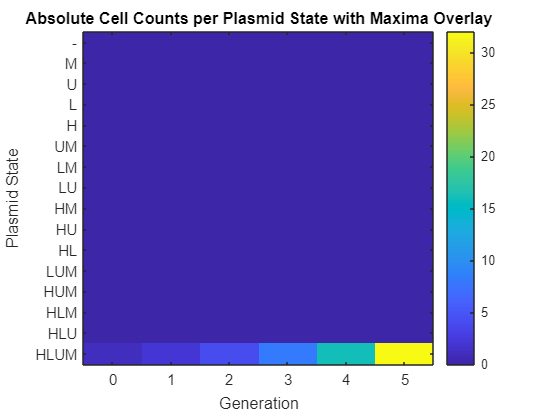


% Plot absolute cell counts in separate figure with max overlay

figure;
imagesc(0:gen,1:16,cell_generation_type'); hold on

colorbar;
% hold on;
% plot(0:num_generations, max_indices, '-w','LineWidth',2);
% hold off;
xlabel('Generation');
ylabel('Plasmid State');
title('Absolute Cell Counts per Plasmid State with Maxima Overlay');
set(gca,'YTick',1:16,'YTickLabel',plasmid_labels);


% % Plot absolute cell counts in separate figure with max overlay
% figure;
% imagesc(0:num_generations,1:16,cell_counts');
% colorbar;
% hold on;
% plot(0:num_generations, max_indices, '-w','LineWidth',2);
% hold off;
% xlabel('Generation');
% ylabel('Plasmid State');
% title('Absolute Cell Counts per Plasmid State with Maxima Overlay');
% set(gca,'YTick',1:16,'YTickLabel',plasmid_labels);
% 
% % Plot probabilities in separate figure
% figure;
% imagesc(0:num_generations,1:16,probabilities');
% colorbar;
% xlabel('Generation');
% ylabel('Plasmid State');
% title('Probability per Plasmid State');
% set(gca,'YTick',1:16,'YTickLabel',plasmid_labels);
% 
% % Display max concentration state per generation
% disp('Max concentration per generation:');
% for gen = 0:num_generations
%     fprintf('Generation %d: Max State = %s, Concentration = %.0f\n', gen, max_labels{gen+1}, max_concs(gen+1));
% end





% Axes
figure;
generations = 0:num_generations;
plasmid_states = 1:16;

% Create meshgrid for surface
[X, Y] = meshgrid(generations, plasmid_states);

% Surface plot of probabilities

surf(X, Y, probabilities', 'EdgeColor', 'none');  % 'EdgeColor','none' for smooth shading
colorbar;
colormap turbo;%, 'hot', 'cool'
shading interp;
% lighting gouraud;
camlight;

xlabel('Generation');
ylabel('Plasmid State');
zlabel('Probability');
title('Probability Surface per Plasmid State');

% Custom tick labels for Y-axis (plasmid states)
set(gca, 'YTick', 1:16, 'YTickLabel', plasmid_labels);

view([125 40])



### Evaluating the correlation

**Description**: This block evaluates the correlation of the PDS with the reference vector b in [1, Fig. 5A]

%% Solve for x given plasmid-combination auxotrophy frequency vector b
plasmid_labels = {'-', 'M', 'U', 'L', 'H', 'UM', 'LM', 'LU', 'HM', 'HU', 'HL', 'LUM', 'HUM', 'HLM', 'HLU', 'HLUM'};
reference_vector=[0 1 19 10 8 2 2 9 2 7 0.5 2 2 4 1 2];
reference_vector(1)=100-sum(reference_vector(2:end));
reference_vector=reference_vector/sum(reference_vector);

% b=[0 1 19 10 8 2 2 9 2 7 0.5 2 2 4 1 5]; % as follows from [1, Fig. 5A]
% b(1)=100-sum(b(2:end));
% 
% b = b / sum(b); % Normalize to sum to 1
% 
% A=zeros(length(plasmid_labels),length(plasmid_labels));
% for i=1:length(plasmid_labels)
%     A(i,:)= ~contains(plasmid_labels,plasmid_labels{i});
% end
% 
% %fully auxotrophic
% A(end,:)=zeros(1,length(plasmid_labels));
% A(end,1)=1;
% %Protrophic auxotrophic
% A(1,:)=zeros(1,length(plasmid_labels));
% A(1,end)=1;
% 
% x=linsolve(A,b');

% Plot inferred cell type distribution
figure;
bar(1:16, reference_vector); grid on;
set(gca,'XTick',1:16,'XTickLabel',plasmid_labels,'XTickLabelRotation',90);
xlabel('Plasmid State');
ylabel('Inferred Proportion');
title('Inferred Cell Type Distribution from Auxotrophy Combinations');

% Calculate correlation of each generation with reference_vector
correlation = zeros(num_generations+1, 1);
for gen = 1:num_generations+1
    correlation(gen) = corr(probabilities(gen,:)', reference_vector');
    % correlation(gen) = corr(probabilities(gen,:)', probabilities(90,:)');
end



% Plot correlation with generation
figure;
plot(0:num_generations, correlation, '-','LineWidth',2);
grid on;
xlabel('Generation','Interpreter','latex');
ylabel('Correlation','Interpreter','latex');
%title('Correlation with Reference Probability Vector over Generations');
set(gca,"FontSize",font)

rectangle('Position',[25 0.5 60 0.45],'LineStyle','--','Curvature',0.2); hold on;
h=annotation('arrow');

 
p = get(gca, 'Position');
h = axes('Parent', gcf, 'Position', [p(1)+0.45 p(2)+0.45 p(3)-.5 p(4)-.5]);

plot(0:num_generations, correlation, '-','LineWidth',2); grid on; hold on
[v,I]=max(correlation)
plot(I,v, 'o','LineWidth',2); grid on; hold on

set(h,'FontSize',font);
set(h, 'Xlim', [25 85], 'Ylim', [0.5 0.95]);



### References

[1] Kate Campbell, Jakob Vowinckel, Michael Mülleder, Silke Malmsheimer, Nicola Lawrence, Enrica Calvani, Leonor Miller-Fleming, Mohammad T Alam, Stefan Christen, Markus A Keller, Markus Ralser (2015) Self-establishing communities enable cooperative metabolite exchange in a eukaryote eLife 4:e09943